# Applying Reaction Mass AUV model to BlueROV2

Modelling script originally written by James Fleming and Will Midgley, modified by Jack Adams

Reaction mass mounted below CoG and CoG below CoB.

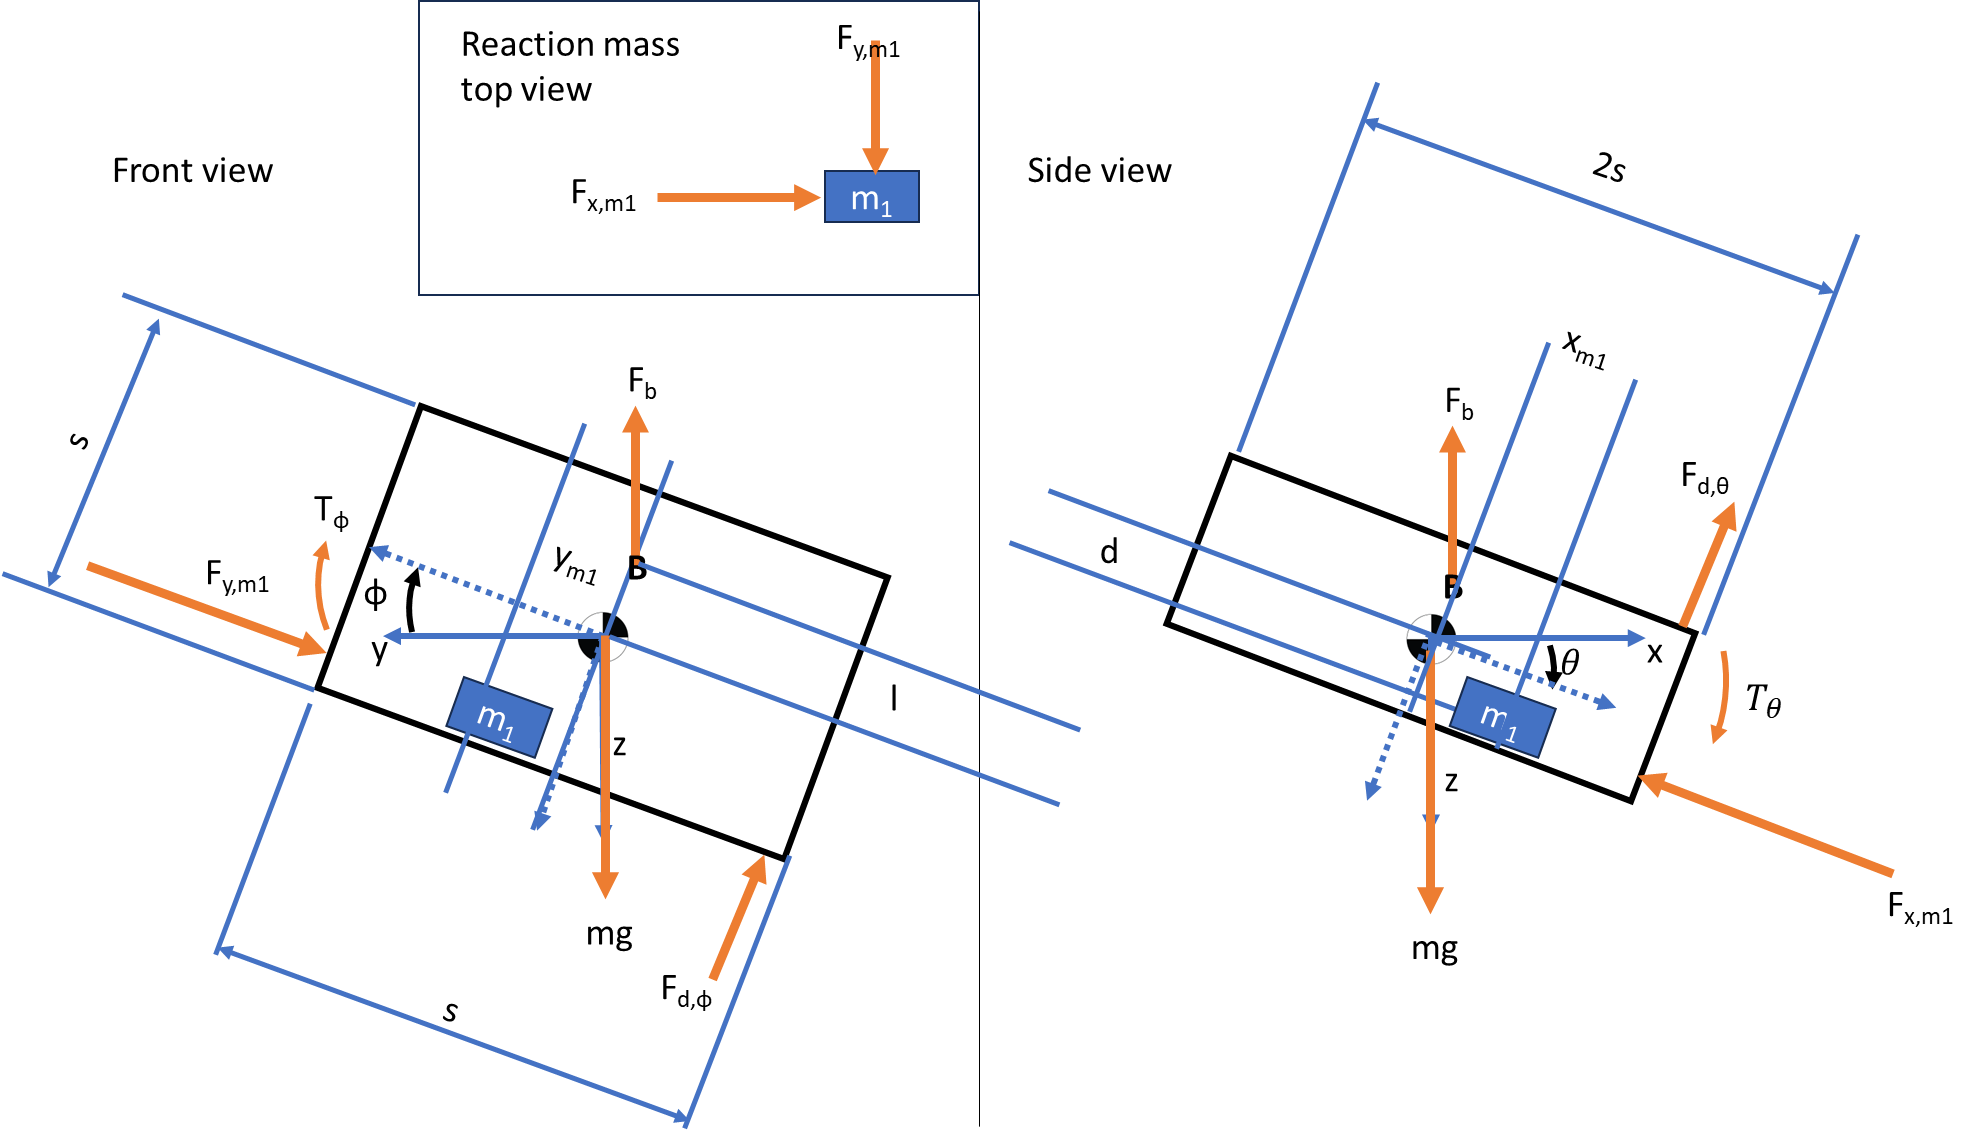

clear;

% theta - pitch angle;
% phi - roll angle;
% x_m - relative reaction mass location in x;
% y_m - relative reaction mass location in y
syms theta(t) phi(t) x_m(t) y_m(t)
% reaction force inputs: F_x, F_y
syms F_x F_y T_theta T_phi

% define generalised co-ords:
q(t) = [theta(t) phi(t) x_m(t) y_m(t)];
% define system inputs:
U = [T_theta; T_phi; F_x; F_y];

% Parameters of the BlueROV2:
params = struct;
syms m M s d l g C_d rho
mass_actuators = 2.22;
params.m = 1.6; % reaction mass mass
params.M = 13.5 + mass_actuators; % AUV mass
params.l = 0.05; % height of CoB above CoM   (Estimated)
params.d = 0.2; % distance below *CoM* for reaction mass   (Estimated)   
params.g = 9.81; % gravitational acceleration
params.rho = 1000;      % Density of water (Jack: Changed to freshwater for pool)

% Volume
Vol_additional_enclosure = 0.0025;
Vol_ROV2 = 0.0134;
Vol = Vol_ROV2 + Vol_additional_enclosure;

% Inertia parameters
I_x = 0.26;
I_y = 0.23;
I_z = 0.37;

% Added mass coefficients
Xu_dot = 6.36;
Yv_dot = 7.12;
Zw_dot = 18.68;
Kp_dot = 0.189;
Mq_dot = 0.135;
Nr_dot = 0.222;

% Linear drag coefficients
Xu = 13.7;
Yv = 0;
Zw = 33.0;
Kp = 0.0;
Mq = 0.8;
Nr = 0.0;

% Nonlinear drag coefficients
Xu_abs_u = 141.0;
Yv_abs_v = 217.0;
Zw_abs_w = 190.0;
Kp_abs_p = 1.19;
Mq_abs_q = 0.47;
Nr_abs_r = 1.5;

## Kinematics

Frames of reference: world frame, body frame and reaction mass frame 

M_01 = rotY(-theta); % pitch from zero point
M_12 = rotX(phi); % roll (now in rotated frame defined by the pitch angle)
M_02 = simplify(M_01*M_12); % from AUV body to world
% CoG points
p_m = M_02*[x_m(t);y_m(t);d;1]; % position of reaction mass
p_M = M_02*[0;0;0;1];   % AUV mass at origin of body frame
p_b = M_02*[0;0;-l;1];   % centre of bouyancy position in body frame (note z positive DOWN)

## Dynamics

% Moment of inertia (Reaction mass is assumed to be a point mass)
J_RB = diag([I_x, I_y, I_z]);   % Rigid body Inertia matrix
J_A = -diag([Kp_dot, Mq_dot, Nr_dot]);  % Added mass Inertia matrix
J = J_A + J_RB;

% velocity of reaction mass
v_m = simplify(diff(p_m,t))


% Angular velocities of theta and phi
M_02 = M_02(t); R_02 = M_02(1:3,1:3);   % Rotation matrix 
Omega2 = simplify(diff(R_02.',t)*R_02);     % % roll velocity using angular velocity tensor 
omega2 = [Omega2(3,2);Omega2(1,3);Omega2(2,1)]     % angular velocity (pseudo)vector

$$omega2 = \left(\begin{array}{c} -\frac{\partial }{\partial t}\varphi \left(t\right)\\ \cos\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\\ -\sin\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right) \end{array}\right)$$


% Kinetic energy of whole mechanism in world frame (JF: Unlike the SCARA example,
% rotations are not coplanar, so must transform the inertia tensors!)
T = massKE(m, v_m) + ... % reaction mass KE
    rotationKE(J,omega2);  % AUV rotation KE

T = simplify(expand(T))

$$T(t) = \begin{array}{l} \frac{71\,\sigma_{3}}{2000}+\frac{37\,\sigma_{1}}{500}-\frac{53\,\sigma_{2}\,\sigma_{1}}{2000}+\frac{m\,{\left(\frac{\partial }{\partial t}x_{m}\left(t\right)\right)}^{2}}{2}+\frac{m\,{\left(\frac{\partial }{\partial t}y_{m}\left(t\right)\right)}^{2}}{2}+\frac{m\,{y_{m}\left(t\right)}^{2}\,\sigma_{3}}{2}+\frac{m\,{x_{m}\left(t\right)}^{2}\,\sigma_{1}}{2}+\frac{m\,{y_{m}\left(t\right)}^{2}\,\sigma_{1}}{2}+\frac{d^{2}\,m\,\sigma_{3}}{2}+\frac{d^{2}\,m\,\sigma_{2}\,\sigma_{1}}{2}-d\,m\,\frac{\partial }{\partial t}y_{m}\left(t\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)-\frac{m\,\sigma_{2}\,{y_{m}\left(t\right)}^{2}\,\sigma_{1}}{2}+m\,\sin\left(\varphi \left(t\right)\right)\,x_{m}\left(t\right)\,\frac{\partial }{\partial t}y_{m}\left(t\right)\,\frac{\partial }{\partial t}\theta \left(t\right)-m\,\sin\left(\varphi \left(t\right)\right)\,y_{m}\left(t\right)\,\frac{\partial }{\partial t}x_{m}\left(t\right)\,\frac{\partial }{\partial t}\theta \left(t\right)+\frac{d\,m\,\sin\left(2\,\varphi \left(t\right)\right)\,y_{m}\left(t\right)\,\sigma_{1}}{2}-d\,m\,\cos\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}x_{m}\left(t\right)\,\frac{\partial }{\partial t}\theta \left(t\right)+m\,\cos\left(\varphi \left(t\right)\right)\,x_{m}\left(t\right)\,y_{m}\left(t\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)-d\,m\,\sin\left(\varphi \left(t\right)\right)\,x_{m}\left(t\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}\\ \sigma_{2}={\cos\left(\varphi \left(t\right)\right)}^{2}\\ \sigma_{3}={\left(\frac{\partial }{\partial t}\varphi \left(t\right)\right)}^{2} \end{array}$$


% z-coordinates of reaction mass, AUV mass (at origin), and bouyancy centre
z_m = [0,0,1,0]*p_m;
z_M = [0,0,1,0]*p_M;
z_b = [0,0,1,0]*p_b;

% Potential energy of whole mechanism 
Vg = -m*g*z_m - M*g*z_M;      % gravity part (JF: be careful here, z is DOWN)
Vb = rho*Vol*g*z_b;    % potential due to bouyancy
V = Vg + Vb;

% Lagrangian and Euler-Lagrange equations
L = T - V;
L_p = subs(L, params);
% EOM = simplify(functionalDerivative(L_p,q(t))) == U
EOM = simplify(functionalDerivative(L,q(t))) == U         % this version will keep the parameters visible

## Second order form of equations of motion

To understand them better, let's put the EOMs into the following form


$$M(q) \ddot{q} + c(q,\dot{q}) + g(q) = u$$


where 'u' is the vector of inputs, i.e. joint torques and forces, c(.,.) contains coriolis and centrifugal terms, g() is gravity and bouyancy.

% Mass matrix should be the same as the Jacobian w.r.t accelerations
M_nl = jacobian(lhs(EOM), diff(q(t),t,t))

% Gravitational part is what is left when no velocity or acceleration
g_nl = subs(lhs(EOM),[diff(q(t),t);diff(q(t),t,t)],[zeros(1,4);zeros(1,4)])
% Find coriolis and centrifugal terms by looking at what remains when 
% inertial and gravitational force terms are removed:
c_nl = subs(lhs(EOM),diff(q(t),t,t),zeros(1,4)) - g_nl

## Find equilibrium configurations for constant external torque

% JF - Look for equilibrium configurations (all terms disappear except g() and U):
syms Theta Phi X_m Y_m
equil = subs(g_nl,[theta phi x_m y_m],[Theta Phi X_m Y_m]) == U
eq = solve(equil,[T_theta T_phi F_x F_y]);
T_theta_eq = eq.T_theta
T_phi_eq = eq.T_phi
F_x_eq = eq.F_x
F_y_eq = eq.F_y

### Look at constant x_m and y_m with zero angles:

% WM: just to look at equilibriums and check I understand code
equil2 = subs(g_nl,[theta phi x_m y_m],[0 0 X_m Y_m]) == U
solve(equil2,[X_m Y_m F_x F_y])

### Convert system to nonlinear state space form

% First convert to SS representation (JF: now working but slow - instead use second order or descriptor form?)
[EOM_rhs, S] = stateSpaceEquations(EOM, {theta phi x_m y_m});

### Calculate stabilising state feedback gain u=Kx around some linearisation point

% then set operating point (should be an equilbrium point! - JF)
% %S =
%     Theta
% Theta_dot
%       Phi
%   Phi_dot
%       X_m
%   X_m_dot
%       Y_m
%   Y_m_dot
S_op = [0; 0; 0; 0; 0; 0; 0; 0];

% % Find steady-state inputs required for equilibrium at this operating point:
Ueq = struct;
Ueq.T_phi = subs(subs(T_phi_eq, S, S_op), params);
Ueq.T_theta = subs(subs(T_theta_eq, S, S_op), params);
Ueq.F_x = subs(subs(F_x_eq, S, S_op), params);
Ueq.F_y = subs(subs(F_y_eq, S, S_op), params)

% A matrix from JF's inverted pendulum
A_nl = subs(jacobian(EOM_rhs, S), Ueq);
A_lin = subs(A_nl, S, S_op);

% B matrix also from JF inverted pendulum example
B_nl = subs(jacobian(EOM_rhs, U), Ueq);
B_lin = subs(B_nl, S, S_op);

% ------
B_lin(:, 1:2) = [];     % Cut torque columns from B Matrix
% ------

A = double(subs(A_lin, params));
B = double(subs(B_lin, params));

% check controllability
Co = ctrb(A,B);
unco = length(A) - rank(Co)

% LQR to penalise only roll, pitch outputs and derivatives
C = [diag([1e0,1e0,1e0,1e0]), zeros(4)];
Q = C'*C;
% R = diag([1e-2,1e-2,1e-2,1e-2]);
R = diag([1e-2,1e-2]); % When cutting torque columns from B Matrix

K = -lqr(A,B,Q,R);
% check eigenvalues
eig(A + B*K)

### Create Simulink model

EOM_rhs = subs(EOM_rhs, params);
IC = '[0; 0; 0; 0; 0; 0; 0; 0]'; % initial conditions

U_op = double([Ueq.T_theta; Ueq.T_phi; Ueq.F_x; Ueq.F_y]);
stateFeedbackModel(EOM_rhs, S, U, IC, K, S_op, U_op, 'model_final_0')